## Q3 - part a | ARX

clc; clear;


%%

load q3_402123100.mat

u1_val = u2;
y1_val = y2;

u2_val = u1;
y2_val = y1;


### Guassian Input - PRBS Validation


%%
% Guassian Input **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> Guassian Input Identification Begins:------------------------------\n")

>>> Guassian Input Identification Begins:------------------------------



%%
Ts = 0.1; 
t = 0:Ts:length(u1)*Ts-Ts;
t_val = 0:Ts:length(u1_val)*Ts-Ts;
N = length(y1);
N_val = length(y1_val);

%%

fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb;
    
    U = arx_U_builder_3(u1, y1, na, nb, nk);
    theta_hat_1 = inv(U'*U)*U'*y1;
    y_hat_1 = form_tf_lsim_2(theta_hat_1, u1, t, na, Ts);

    [r2_arx, mse_arx] = rSQR(y1, y_hat_1);

    error = y1 - y_hat_1;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    covariance = variance*inv(U'*U);
    cov = trace(covariance)/p;
    covs = [covs; cov];

    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_arx, mse_arx, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_arx];
    MSEs = [MSEs; mse_arx];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.893369 | MSE=0.028697 | var=0.028711 | s_hat=117.541609 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.921083 | MSE=0.021238 | var=0.021259 | s_hat=86.991301 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.935419 | MSE=0.017380 | var=0.017406 | s_hat=71.189426 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.940151 | MSE=0.016107 | var=0.016138 | s_hat=65.973187 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.940996 | MSE=0.015879 | var=0.015918 | s_hat=65.041472 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.940908 | MSE=0.015903 | var=0.015950 | s_hat=65.138384 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.940825 | MSE=0.015925 | var=0.015980 | s_hat=65.229326 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.940875 | MSE=0.015912 | var=0.015974 | s_hat=65.174834 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.941038 | MSE=0.015868 | var=0.015938 | s_hat=64.994673 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.941086 | MSE=0.015855 | var=0.015933 | s_hat=64.941520 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.941092 | MSE=0.015853 | var=0.015939 | s_hat=64.935054 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.941090 | MSE=0.015854 | var=0.015947 | s_hat=64.937948 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.941094 | MSE=0.015853 | var=0.015954 | s_hat=64.932930 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.941106 | MSE=0.015850 | var=0.015959 | s_hat=64.919906 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.941135 | MSE=0.015842 | var=0.015959 | s_hat=64.888210 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.941138 | MSE=0.015841 | var=0.015966 | s_hat=64.884185 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.941140 | MSE=0.015840 | var=0.015973 | s_hat=64.882604 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.941148 | MSE=0.015838 | var=0.015979 | s_hat=64.873412 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.941198 | MSE=0.015825 | var=0.015973 | s_hat=64.818534 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.941197 | MSE=0.015825 | var=0.015981 | s_hat=64.819543 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.941199 | MSE=0.015825 | var=0.015989 | s_hat=64.817919 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.941218 | MSE=0.015819 | var=0.015991 | s_hat=64.796573 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.941197 | MSE=0.015825 | var=0.016005 | s_hat=64.819753 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.941259 | MSE=0.015808 | var=0.015996 | s_hat=64.750954 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.941274 | MSE=0.015804 | var=0.016000 | s_hat=64.735108 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.941273 | MSE=0.015805 | var=0.016008 | s_hat=64.735598 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.941288 | MSE=0.015801 | var=0.016012 | s_hat=64.719315 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.941342 | MSE=0.015786 | var=0.016005 | s_hat=64.660046 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.941490 | MSE=0.015746 | var=0.015972 | s_hat=64.496433 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.941492 | MSE=0.015746 | var=0.015980 | s_hat=64.494680 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.941495 | MSE=0.015745 | var=0.015987 | s_hat=64.490803 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.941498 | MSE=0.015744 | var=0.015994 | s_hat=64.488439 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.941493 | MSE=0.015745 | var=0.016003 | s_hat=64.493340 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.941526 | MSE=0.015736 | var=0.016002 | s_hat=64.456559 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.941518 | MSE=0.015739 | var=0.016012 | s_hat=64.465609 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.941524 | MSE=0.015737 | var=0.016019 | s_hat=64.459198 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.941517 | MSE=0.015739 | var=0.016029 | s_hat=64.467224 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.941565 | MSE=0.015726 | var=0.016023 | s_hat=64.414385 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.941648 | MSE=0.015704 | var=0.016009 | s_hat=64.322692 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.941671 | MSE=0.015697 | var=0.016010 | s_hat=64.296677 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.941672 | MSE=0.015697 | var=0.016018 | s_hat=64.295667 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.941672 | MSE=0.015697 | var=0.016026 | s_hat=64.295835 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.941671 | MSE=0.015698 | var=0.016034 | s_hat=64.297409 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.941678 | MSE=0.015696 | var=0.016040 | s_hat=64.289505 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.941701 | MSE=0.015690 | var=0.016042 | s_hat=64.264299 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.941702 | MSE=0.015689 | var=0.016050 | s_hat=64.263342 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.941701 | MSE=0.015689 | var=0.016058 | s_hat=64.263776 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.941724 | MSE=0.015683 | var=0.016060 | s_hat=64.239120 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.941752 | MSE=0.015676 | var=0.016060 | s_hat=64.207365 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.941756 | MSE=0.015675 | var=0.016067 | s_hat=64.203447 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.941777 | MSE=0.015669 | var=0.016069 | s_hat=64.180813 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.941790 | MSE=0.015666 | var=0.016074 | s_hat=64.166528 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.941795 | MSE=0.015664 | var=0.016080 | s_hat=64.160593 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.941834 | MSE=0.015654 | var=0.016077 | s_hat=64.116976 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.941868 | MSE=0.015645 | var=0.016076 | s_hat=64.080445 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.941888 | MSE=0.015639 | var=0.016079 | s_hat=64.057756 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.941913 | MSE=0.015632 | var=0.016080 | s_hat=64.030009 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.941961 | MSE=0.015620 | var=0.016075 | s_hat=63.977504 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.942054 | MSE=0.015594 | var=0.016057 | s_hat=63.874931 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.942057 | MSE=0.015594 | var=0.016064 | s_hat=63.871439 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.942151 | MSE=0.015568 | var=0.016046 | s_hat=63.767683 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.942163 | MSE=0.015565 | var=0.016051 | s_hat=63.755093 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.942164 | MSE=0.015565 | var=0.016059 | s_hat=63.754258 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.942154 | MSE=0.015567 | var=0.016070 | s_hat=63.764408 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.942182 | MSE=0.015560 | var=0.016070 | s_hat=63.734375 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.942203 | MSE=0.015554 | var=0.016072 | s_hat=63.710548 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=0.942195 | MSE=0.015557 | var=0.016083 | s_hat=63.719656 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.942201 | MSE=0.015555 | var=0.016089 | s_hat=63.713365 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=0.942215 | MSE=0.015551 | var=0.016093 | s_hat=63.697869 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.942217 | MSE=0.015550 | var=0.016101 | s_hat=63.694837 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=0.942214 | MSE=0.015551 | var=0.016110 | s_hat=63.698685 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=0.942185 | MSE=0.015559 | var=0.016126 | s_hat=63.730056 | 


-------------------------------------------------------------


>>> Degree = 73 : R2=0.942222 | MSE=0.015549 | var=0.016124 | s_hat=63.689508 | 


-------------------------------------------------------------


>>> Degree = 74 : R2=0.942225 | MSE=0.015549 | var=0.016131 | s_hat=63.686915 | 


-------------------------------------------------------------


>>> Degree = 75 : R2=0.942253 | MSE=0.015541 | var=0.016132 | s_hat=63.656097 | 


-------------------------------------------------------------


>>> Degree = 76 : R2=0.942272 | MSE=0.015536 | var=0.016134 | s_hat=63.634316 | 


-------------------------------------------------------------


>>> Degree = 77 : R2=0.942278 | MSE=0.015534 | var=0.016141 | s_hat=63.628294 | 


-------------------------------------------------------------


>>> Degree = 78 : R2=0.942289 | MSE=0.015531 | var=0.016146 | s_hat=63.616145 | 


-------------------------------------------------------------


>>> Degree = 79 : R2=0.942284 | MSE=0.015533 | var=0.016156 | s_hat=63.621317 | 


-------------------------------------------------------------


>>> Degree = 80 : R2=0.942299 | MSE=0.015529 | var=0.016160 | s_hat=63.604835 | 


-------------------------------------------------------------


>>> Degree = 81 : R2=0.942347 | MSE=0.015516 | var=0.016155 | s_hat=63.552315 | 


-------------------------------------------------------------


>>> Degree = 82 : R2=0.942369 | MSE=0.015510 | var=0.016157 | s_hat=63.527831 | 


-------------------------------------------------------------


>>> Degree = 83 : R2=0.942384 | MSE=0.015506 | var=0.016161 | s_hat=63.511142 | 


-------------------------------------------------------------


>>> Degree = 84 : R2=0.942416 | MSE=0.015497 | var=0.016160 | s_hat=63.475808 | 


-------------------------------------------------------------


>>> Degree = 85 : R2=0.942431 | MSE=0.015493 | var=0.016164 | s_hat=63.459004 | 


-------------------------------------------------------------


>>> Degree = 86 : R2=0.942432 | MSE=0.015493 | var=0.016172 | s_hat=63.458308 | 


-------------------------------------------------------------


>>> Degree = 87 : R2=0.942430 | MSE=0.015493 | var=0.016181 | s_hat=63.460029 | 


-------------------------------------------------------------


>>> Degree = 88 : R2=0.942431 | MSE=0.015493 | var=0.016189 | s_hat=63.458969 | 


-------------------------------------------------------------


>>> Degree = 89 : R2=0.942441 | MSE=0.015490 | var=0.016194 | s_hat=63.448653 | 


-------------------------------------------------------------


>>> Degree = 90 : R2=0.942464 | MSE=0.015484 | var=0.016196 | s_hat=63.422611 | 


-------------------------------------------------------------


>>> Degree = 91 : R2=0.942504 | MSE=0.015473 | var=0.016193 | s_hat=63.379223 | 


-------------------------------------------------------------


>>> Degree = 92 : R2=0.942508 | MSE=0.015472 | var=0.016200 | s_hat=63.374970 | 


-------------------------------------------------------------


>>> Degree = 93 : R2=0.942531 | MSE=0.015466 | var=0.016202 | s_hat=63.349616 | 


-------------------------------------------------------------


>>> Degree = 94 : R2=0.942526 | MSE=0.015467 | var=0.016211 | s_hat=63.354408 | 


-------------------------------------------------------------


>>> Degree = 95 : R2=0.942551 | MSE=0.015461 | var=0.016213 | s_hat=63.327613 | 


-------------------------------------------------------------


>>> Degree = 96 : R2=0.942572 | MSE=0.015455 | var=0.016215 | s_hat=63.303681 | 


-------------------------------------------------------------


>>> Degree = 97 : R2=0.942578 | MSE=0.015454 | var=0.016222 | s_hat=63.297899 | 


-------------------------------------------------------------


>>> Degree = 98 : R2=0.942582 | MSE=0.015452 | var=0.016229 | s_hat=63.293225 | 


-------------------------------------------------------------


>>> Degree = 99 : R2=0.942589 | MSE=0.015451 | var=0.016235 | s_hat=63.285413 | 


-------------------------------------------------------------


>>> Degree = 100 : R2=0.942601 | MSE=0.015447 | var=0.016240 | s_hat=63.272015 | 


-------------------------------------------------------------



fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 100 


na = bestFitDegree;
nb = bestFitDegree;
p = na+nb;

BestFitU = arx_U_builder_3(u1, y1, na, nb, nk);
BestFitModel_1 = inv(BestFitU'*BestFitU)*BestFitU'*y1;
BestFit_y_hat_1 = form_tf_lsim_2(BestFitModel_1, u1_val, t_val, na, Ts);

G =
 
                                                                                                           
  0.3952 z^-1 + 0.2013 z^-2 + 0.05884 z^-3 - 0.01008 z^-4 - 0.04394 z^-5 - 0.04718 z^-6 - 0.03742 z^-7     
                                                                                                           
          - 0.02346 z^-8 - 0.002027 z^-9 + 0.005351 z^-10 + 0.02352 z^-11 + 0.01018 z^-12 + 0.001935 z^-13 
                                                                                                           
          + 0.002625 z^-14 - 0.005436 z^-15 - 0.01269 z^-16 - 0.00866 z^-17 - 0.002842 z^-18               
                                                                                                           
          + 0.007692 z^-19 + 0.01169 z^-20 + 0.007725 z^-21 + 0.005266 z^-22 - 0.01339 z^-23               
                                                                                                           
          - 0.001967 z


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 5 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 5 


na = minVarIndex;
nb = minVarIndex;
p = na+nb;

VarU = arx_U_builder_3(u1, y1, na, nb, nk);
VarModel_1 = inv(VarU'*VarU)*VarU'*y1;
Var_y_hat_1 = form_tf_lsim_2(VarModel_1, u1_val, t_val, na, Ts);

G =
 
    0.3951 z^-1 + 0.1927 z^-2 + 0.04997 z^-3 - 0.01372 z^-4 - 0.02994 z^-5
  ---------------------------------------------------------------------------
  1 - 0.1897 z^-1 - 0.08256 z^-2 - 0.01541 z^-3 + 0.01903 z^-4 + 0.07503 z^-5
 
Sample time: 0.1 seconds
Discrete-time transfer function.




fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | CoVariance Method=================\n")

===============Degree Extraction | CoVariance Method=================



maxCovIndex = find(covs == min(covs));
fprintf(">>> Since the minimum CovMatrix trace occurs in iteration %d ;\n", maxCovIndex)

>>> Since the minimum CovMatrix trace occurs in iteration 1 ;


fprintf("    Degree = %d \n", maxCovIndex)

    Degree = 1 


na = maxCovIndex;
nb = maxCovIndex;
p = na+nb;

CovU_1 = arx_U_builder_3(u1,y1,na,nb,1);
CovModel_1 = inv(CovU_1'*CovU_1)*CovU_1'*y1;

CovU_1_val = arx_U_builder_3(u1_val,y1_val,na,nb,1);
Cov_y_hat_1 = CovU_1_val*CovModel_1;

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 5 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 5 



na = minAICIndex;
nb = minAICIndex;
p = na+nb;

AICU_1 = arx_U_builder_3(u1, y1, na, nb, nk);
AICModel_1 = inv(AICU_1'*AICU_1)*AICU_1'*y1;
AIC_y_hat_1 = form_tf_lsim_2(AICModel_1, u1_val, t_val, na, Ts);

G =
 
    0.3951 z^-1 + 0.1927 z^-2 + 0.04997 z^-3 - 0.01372 z^-4 - 0.02994 z^-5
  ---------------------------------------------------------------------------
  1 - 0.1897 z^-1 - 0.08256 z^-2 - 0.01541 z^-3 + 0.01903 z^-4 + 0.07503 z^-5
 
Sample time: 0.1 seconds
Discrete-time transfer function.




fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.18 as


fprintf("    Degree = %d \n", winner)

    Degree = 5 



na = winner;
nb = winner;
p = na+nb;

FTestU_1 = arx_U_builder_3(u1, y1, na, nb, nk);
FTestModel_1 = inv(FTestU_1'*FTestU_1)*FTestU_1'*y1;
FTest_y_hat_1 = form_tf_lsim_2(FTestModel_1, u1_val, t_val, na, Ts);

G =
 
    0.3951 z^-1 + 0.1927 z^-2 + 0.04997 z^-3 - 0.01372 z^-4 - 0.02994 z^-5
  ---------------------------------------------------------------------------
  1 - 0.1897 z^-1 - 0.08256 z^-2 - 0.01541 z^-3 + 0.01903 z^-4 + 0.07503 z^-5
 
Sample time: 0.1 seconds
Discrete-time transfer function.




fprintf("=================================================================\n")


%%

[BestFit_r2, BestFit_mse] = rSQR(y1_val, BestFit_y_hat_1);
[Var_r2, Var_mse] = rSQR(y1_val, Var_y_hat_1);
[AIC_r2, AIC_mse] = rSQR(y1_val, AIC_y_hat_1);
[Cov_r2, Cov_mse] = rSQR(y1_val, Cov_y_hat_1);
[FTest_r2, FTest_mse] = rSQR(y1_val, FTest_y_hat_1);
fprintf("===========================PRBS Ident - Guassian ValidI===========================\n")

===========================PRBS Ident - Guassian ValidI===========================


fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", BestFit_r2, BestFit_mse)

    R2 value : 0.9419   | MSE : 0.0155 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Var_r2, Var_mse)

    R2 value : 0.9429   | MSE : 0.0152 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Covariance Method:\n")

>>> Covariance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Cov_r2, Cov_mse)

    R2 value : 0.9167   | MSE : 0.0222 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", AIC_r2, AIC_mse)

    R2 value : 0.9429   | MSE : 0.0152 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", FTest_r2, FTest_mse)

    R2 value : 0.9429   | MSE : 0.0152 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")


%%

BestFitError_1 = y1_val - BestFit_y_hat_1;
VarError_1 = y1_val - Var_y_hat_1;
CovError_1 = y1_val - Cov_y_hat_1;
AICError_1 = y1_val - AIC_y_hat_1;
FTestError_1 = y1_val - FTest_y_hat_1;

for k=0:N_val-1
    BestFit_Ree_1(k+1,1) = AutoCorrelate(BestFitError_1, k);
    Var_Ree_1(k+1,1) = AutoCorrelate(VarError_1, k);
    Cov_Ree_1(k+1,1) = AutoCorrelate(CovError_1, k);
    AIC_Ree_1(k+1,1) = AutoCorrelate(AICError_1, k);
    FTest_Ree_1(k+1,1) = AutoCorrelate(FTestError_1, k);
end

for k=0:N_val-1
    BestFit_Rue_1(k+1,1) = CrossCorrelate(u1_val, BestFitError_1, k);
    Var_Rue_1(k+1,1) = CrossCorrelate(u1_val, VarError_1, k);
    Cov_Rue_1(k+1,1) = CrossCorrelate(u1_val, CovError_1, k);
    AIC_Rue_1(k+1,1) = CrossCorrelate(u1_val, AICError_1, k);
    FTest_Rue_1(k+1,1) = CrossCorrelate(u1_val, FTestError_1, k);
end

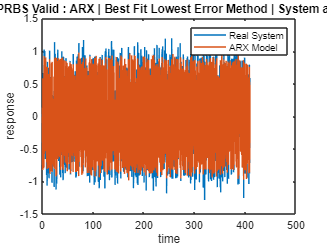



%%
figure()  % figure(1)
plot(t_val,y1_val,t_val,BestFit_y_hat_1)
legend('Real System','ARX Model')
title(" Guassian Ident - PRBS Valid : ARX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

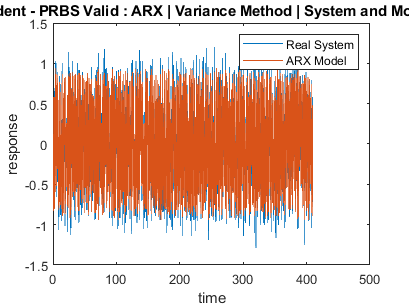


figure()  % figure(2)
plot(t_val,y1_val,t_val,Var_y_hat_1)
legend('Real System','ARX Model')
title(" Guassian Ident - PRBS Valid : ARX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

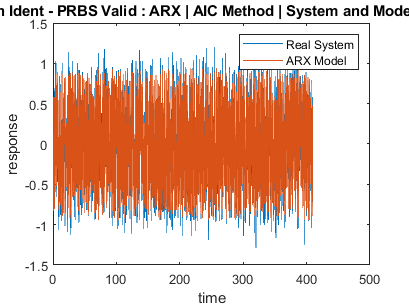


figure()  % figure(3)
plot(t_val,y1_val,t_val,AIC_y_hat_1)
legend('Real System','ARX Model')
title(" Guassian Ident - PRBS Valid : ARX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

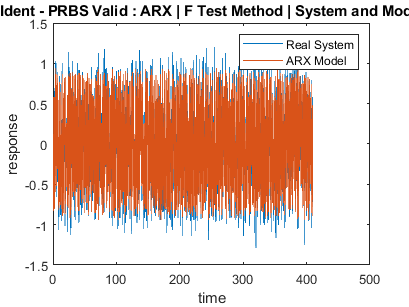


figure()  % figure(4)
plot(t_val,y1_val,t_val,FTest_y_hat_1)
legend('Real System','ARX Model')
title(" Guassian Ident - PRBS Valid : ARX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

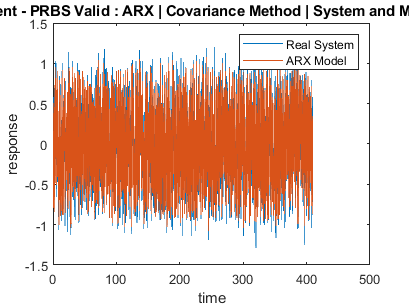


figure()  % figure(7)
plot(t_val,y1_val,t_val,Cov_y_hat_1)
legend('Real System','ARX Model')
title(" Guassian Ident - PRBS Valid : ARX | Covariance Method | System and Model Response")
xlabel("time")
ylabel("response")


%%

figure()  % figure(5)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Ree_1(2:end), 1:N_val-1, mean(BestFit_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARX | Best Fit Lowest Errror Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Ree_1(2:end), 1:N_val-1, mean(Var_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARX | Variance Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Ree_1(2:end), 1:N_val-1, mean(AIC_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARX | AIC Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Ree_1(2:end), 1:N_val-1, mean(FTest_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARX | F Test Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,5)
plot(1:N_val-1,Cov_Ree_1(2:end), 1:N_val-1, mean(Cov_Ree_1(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARX | Covariance Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")



%%

figure()  % figure(6)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Rue_1(2:end), 1:N_val-1, mean(BestFit_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARX | Best Fit Lowest Errror Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Rue_1(2:end), 1:N_val-1, mean(Var_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARX | Variance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Rue_1(2:end), 1:N_val-1, mean(AIC_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARX | AIC Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Rue_1(2:end), 1:N_val-1, mean(FTest_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARX | F Test Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,5)
plot(1:N_val-1,Cov_Rue_1(2:end), 1:N_val-1, mean(Cov_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" Guassian Ident - PRBS Valid : ARX | Covariance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")




%%

figure()  % figure(6)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Rue_1(2:end), 1:N_val-1, mean(BestFit_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" ARX | Best Fit Lowest Errror Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Rue_1(2:end), 1:N_val-1, mean(Var_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" ARX | Variance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Rue_1(2:end), 1:N_val-1, mean(AIC_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" ARX | AIC Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Rue_1(2:end), 1:N_val-1, mean(FTest_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" ARX | F Test Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")


subplot(5,1,5)
plot(1:N_val-1,Cov_Rue_1(2:end), 1:N_val-1, mean(Cov_Rue_1(2:end))*ones(length(1:N_val-1)))
title(" ARX | Covariance Method | Rue_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_1(k)")


% ************************************************************************

fprintf("*****************************************************************\n")
fprintf("*****************************************************************\n")



### PRBS Input - Guassian Validation

%%
% PRBS Input **************************************************************
fprintf("*****************************************************************\n")

*****************************************************************


fprintf(">>> PRBS Input Identification Begins:------------------------------\n")

>>> PRBS Input Identification Begins:------------------------------




%%

Ts = 0.1; 
t = 0:Ts:length(u2)*Ts-Ts;
t_val = 0:Ts:length(u2_val)*Ts-Ts;
N = length(y2);
N_val = length(y2_val);


%%

fprintf("====================Degree Extraction | RUN===========================\n")

====================Degree Extraction | RUN===========================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 0.75;

for degree=1:100
    na = degree;
    nb = degree;
    nk = 1;
    p = na+nb;
    
    U = arx_U_builder_3(u2, y2, na, nb, nk);
    theta_hat_2 = inv(U'*U)*U'*y2;
    y_hat_2 = form_tf_lsim_2(theta_hat_2, u2, t, na, Ts);

    [r2_arx, mse_arx] = rSQR(y2, y_hat_2);

    error = y2 - y_hat_2;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end

    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);
    
    covariance = variance*inv(U'*U);
    cov = trace(covariance)/p;
    covs = [covs; cov];

    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f | s_hat=%f | \n", degree, r2_arx, mse_arx, variance, S_hat)
    fprintf("-------------------------------------------------------------\n")

    ps = [ps; p];
    R2s = [R2s; r2_arx];
    MSEs = [MSEs; mse_arx];
    vars = [vars; variance];    
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    
end

>>> Degree = 1 : R2=0.895788 | MSE=0.027773 | var=0.027787 | s_hat=113.760130 | 


-------------------------------------------------------------


>>> Degree = 2 : R2=0.920829 | MSE=0.021100 | var=0.021120 | s_hat=86.424697 | 


-------------------------------------------------------------


>>> Degree = 3 : R2=0.936579 | MSE=0.016902 | var=0.016927 | s_hat=69.231950 | 


-------------------------------------------------------------


>>> Degree = 4 : R2=0.942226 | MSE=0.015397 | var=0.015427 | s_hat=63.067300 | 


-------------------------------------------------------------


>>> Degree = 5 : R2=0.943224 | MSE=0.015131 | var=0.015168 | s_hat=61.977742 | 


-------------------------------------------------------------


>>> Degree = 6 : R2=0.943283 | MSE=0.015116 | var=0.015160 | s_hat=61.913458 | 


-------------------------------------------------------------


>>> Degree = 7 : R2=0.943220 | MSE=0.015132 | var=0.015184 | s_hat=61.981833 | 


-------------------------------------------------------------


>>> Degree = 8 : R2=0.943242 | MSE=0.015127 | var=0.015186 | s_hat=61.958162 | 


-------------------------------------------------------------


>>> Degree = 9 : R2=0.943319 | MSE=0.015106 | var=0.015173 | s_hat=61.873876 | 


-------------------------------------------------------------


>>> Degree = 10 : R2=0.943355 | MSE=0.015096 | var=0.015170 | s_hat=61.834188 | 


-------------------------------------------------------------


>>> Degree = 11 : R2=0.943382 | MSE=0.015089 | var=0.015171 | s_hat=61.805613 | 


-------------------------------------------------------------


>>> Degree = 12 : R2=0.943384 | MSE=0.015089 | var=0.015178 | s_hat=61.803130 | 


-------------------------------------------------------------


>>> Degree = 13 : R2=0.943432 | MSE=0.015076 | var=0.015172 | s_hat=61.750787 | 


-------------------------------------------------------------


>>> Degree = 14 : R2=0.943431 | MSE=0.015076 | var=0.015180 | s_hat=61.751484 | 


-------------------------------------------------------------


>>> Degree = 15 : R2=0.943439 | MSE=0.015074 | var=0.015185 | s_hat=61.742803 | 


-------------------------------------------------------------


>>> Degree = 16 : R2=0.943426 | MSE=0.015077 | var=0.015196 | s_hat=61.756677 | 


-------------------------------------------------------------


>>> Degree = 17 : R2=0.943468 | MSE=0.015066 | var=0.015192 | s_hat=61.711004 | 


-------------------------------------------------------------


>>> Degree = 18 : R2=0.943478 | MSE=0.015064 | var=0.015197 | s_hat=61.700494 | 


-------------------------------------------------------------


>>> Degree = 19 : R2=0.943483 | MSE=0.015062 | var=0.015203 | s_hat=61.695052 | 


-------------------------------------------------------------


>>> Degree = 20 : R2=0.943481 | MSE=0.015063 | var=0.015211 | s_hat=61.697195 | 


-------------------------------------------------------------


>>> Degree = 21 : R2=0.943520 | MSE=0.015052 | var=0.015208 | s_hat=61.654609 | 


-------------------------------------------------------------


>>> Degree = 22 : R2=0.943533 | MSE=0.015049 | var=0.015212 | s_hat=61.640598 | 


-------------------------------------------------------------


>>> Degree = 23 : R2=0.943527 | MSE=0.015051 | var=0.015222 | s_hat=61.647380 | 


-------------------------------------------------------------


>>> Degree = 24 : R2=0.943521 | MSE=0.015052 | var=0.015231 | s_hat=61.653905 | 


-------------------------------------------------------------


>>> Degree = 25 : R2=0.943516 | MSE=0.015053 | var=0.015239 | s_hat=61.658789 | 


-------------------------------------------------------------


>>> Degree = 26 : R2=0.943588 | MSE=0.015034 | var=0.015228 | s_hat=61.580760 | 


-------------------------------------------------------------


>>> Degree = 27 : R2=0.943606 | MSE=0.015029 | var=0.015230 | s_hat=61.560655 | 


-------------------------------------------------------------


>>> Degree = 28 : R2=0.943618 | MSE=0.015026 | var=0.015235 | s_hat=61.547405 | 


-------------------------------------------------------------


>>> Degree = 29 : R2=0.943632 | MSE=0.015022 | var=0.015238 | s_hat=61.531792 | 


-------------------------------------------------------------


>>> Degree = 30 : R2=0.943624 | MSE=0.015025 | var=0.015248 | s_hat=61.541138 | 


-------------------------------------------------------------


>>> Degree = 31 : R2=0.943649 | MSE=0.015018 | var=0.015249 | s_hat=61.513934 | 


-------------------------------------------------------------


>>> Degree = 32 : R2=0.943682 | MSE=0.015009 | var=0.015247 | s_hat=61.477563 | 


-------------------------------------------------------------


>>> Degree = 33 : R2=0.943689 | MSE=0.015007 | var=0.015253 | s_hat=61.469767 | 


-------------------------------------------------------------


>>> Degree = 34 : R2=0.943734 | MSE=0.014995 | var=0.015249 | s_hat=61.421365 | 


-------------------------------------------------------------


>>> Degree = 35 : R2=0.943742 | MSE=0.014993 | var=0.015254 | s_hat=61.412691 | 


-------------------------------------------------------------


>>> Degree = 36 : R2=0.943751 | MSE=0.014991 | var=0.015259 | s_hat=61.402503 | 


-------------------------------------------------------------


>>> Degree = 37 : R2=0.943763 | MSE=0.014988 | var=0.015263 | s_hat=61.389789 | 


-------------------------------------------------------------


>>> Degree = 38 : R2=0.943803 | MSE=0.014977 | var=0.015260 | s_hat=61.345190 | 


-------------------------------------------------------------


>>> Degree = 39 : R2=0.943814 | MSE=0.014974 | var=0.015265 | s_hat=61.333789 | 


-------------------------------------------------------------


>>> Degree = 40 : R2=0.943813 | MSE=0.014974 | var=0.015273 | s_hat=61.334951 | 


-------------------------------------------------------------


>>> Degree = 41 : R2=0.943817 | MSE=0.014973 | var=0.015279 | s_hat=61.330813 | 


-------------------------------------------------------------


>>> Degree = 42 : R2=0.943847 | MSE=0.014965 | var=0.015279 | s_hat=61.297754 | 


-------------------------------------------------------------


>>> Degree = 43 : R2=0.943871 | MSE=0.014959 | var=0.015280 | s_hat=61.271156 | 


-------------------------------------------------------------


>>> Degree = 44 : R2=0.943903 | MSE=0.014950 | var=0.015278 | s_hat=61.235979 | 


-------------------------------------------------------------


>>> Degree = 45 : R2=0.943920 | MSE=0.014946 | var=0.015281 | s_hat=61.217425 | 


-------------------------------------------------------------


>>> Degree = 46 : R2=0.943921 | MSE=0.014946 | var=0.015289 | s_hat=61.217020 | 


-------------------------------------------------------------


>>> Degree = 47 : R2=0.943912 | MSE=0.014948 | var=0.015299 | s_hat=61.226699 | 


-------------------------------------------------------------


>>> Degree = 48 : R2=0.943992 | MSE=0.014927 | var=0.015285 | s_hat=61.139389 | 


-------------------------------------------------------------


>>> Degree = 49 : R2=0.943997 | MSE=0.014925 | var=0.015291 | s_hat=61.133808 | 


-------------------------------------------------------------


>>> Degree = 50 : R2=0.943998 | MSE=0.014925 | var=0.015298 | s_hat=61.132466 | 


-------------------------------------------------------------


>>> Degree = 51 : R2=0.943996 | MSE=0.014925 | var=0.015307 | s_hat=61.134796 | 


-------------------------------------------------------------


>>> Degree = 52 : R2=0.944011 | MSE=0.014922 | var=0.015310 | s_hat=61.118903 | 


-------------------------------------------------------------


>>> Degree = 53 : R2=0.944013 | MSE=0.014921 | var=0.015317 | s_hat=61.116384 | 


-------------------------------------------------------------


>>> Degree = 54 : R2=0.944045 | MSE=0.014913 | var=0.015316 | s_hat=61.081918 | 


-------------------------------------------------------------


>>> Degree = 55 : R2=0.944043 | MSE=0.014913 | var=0.015324 | s_hat=61.083310 | 


-------------------------------------------------------------


>>> Degree = 56 : R2=0.944069 | MSE=0.014906 | var=0.015325 | s_hat=61.055272 | 


-------------------------------------------------------------


>>> Degree = 57 : R2=0.944067 | MSE=0.014907 | var=0.015333 | s_hat=61.057452 | 


-------------------------------------------------------------


>>> Degree = 58 : R2=0.944079 | MSE=0.014903 | var=0.015338 | s_hat=61.044717 | 


-------------------------------------------------------------


>>> Degree = 59 : R2=0.944084 | MSE=0.014902 | var=0.015344 | s_hat=61.038898 | 


-------------------------------------------------------------


>>> Degree = 60 : R2=0.944129 | MSE=0.014890 | var=0.015339 | s_hat=60.989475 | 


-------------------------------------------------------------


>>> Degree = 61 : R2=0.944137 | MSE=0.014888 | var=0.015345 | s_hat=60.981405 | 


-------------------------------------------------------------


>>> Degree = 62 : R2=0.944144 | MSE=0.014886 | var=0.015351 | s_hat=60.972849 | 


-------------------------------------------------------------


>>> Degree = 63 : R2=0.944145 | MSE=0.014886 | var=0.015358 | s_hat=60.972506 | 


-------------------------------------------------------------


>>> Degree = 64 : R2=0.944172 | MSE=0.014879 | var=0.015359 | s_hat=60.942783 | 


-------------------------------------------------------------


>>> Degree = 65 : R2=0.944187 | MSE=0.014875 | var=0.015362 | s_hat=60.926025 | 


-------------------------------------------------------------


>>> Degree = 66 : R2=0.944190 | MSE=0.014874 | var=0.015369 | s_hat=60.923636 | 


-------------------------------------------------------------


>>> Degree = 67 : R2=0.944193 | MSE=0.014873 | var=0.015376 | s_hat=60.920197 | 


-------------------------------------------------------------


>>> Degree = 68 : R2=0.944205 | MSE=0.014870 | var=0.015381 | s_hat=60.906787 | 


-------------------------------------------------------------


>>> Degree = 69 : R2=0.944214 | MSE=0.014867 | var=0.015386 | s_hat=60.896643 | 


-------------------------------------------------------------


>>> Degree = 70 : R2=0.944227 | MSE=0.014864 | var=0.015390 | s_hat=60.883273 | 


-------------------------------------------------------------


>>> Degree = 71 : R2=0.944252 | MSE=0.014857 | var=0.015391 | s_hat=60.855260 | 


-------------------------------------------------------------


>>> Degree = 72 : R2=0.944343 | MSE=0.014833 | var=0.015374 | s_hat=60.756220 | 


-------------------------------------------------------------


>>> Degree = 73 : R2=0.944349 | MSE=0.014832 | var=0.015380 | s_hat=60.749933 | 


-------------------------------------------------------------


>>> Degree = 74 : R2=0.944378 | MSE=0.014824 | var=0.015379 | s_hat=60.718099 | 


-------------------------------------------------------------


>>> Degree = 75 : R2=0.944378 | MSE=0.014824 | var=0.015387 | s_hat=60.718076 | 


-------------------------------------------------------------


>>> Degree = 76 : R2=0.944383 | MSE=0.014822 | var=0.015394 | s_hat=60.712430 | 


-------------------------------------------------------------


>>> Degree = 77 : R2=0.944403 | MSE=0.014817 | var=0.015396 | s_hat=60.690187 | 


-------------------------------------------------------------


>>> Degree = 78 : R2=0.944404 | MSE=0.014817 | var=0.015403 | s_hat=60.689026 | 


-------------------------------------------------------------


>>> Degree = 79 : R2=0.944416 | MSE=0.014814 | var=0.015408 | s_hat=60.676209 | 


-------------------------------------------------------------


>>> Degree = 80 : R2=0.944417 | MSE=0.014813 | var=0.015416 | s_hat=60.675471 | 


-------------------------------------------------------------


>>> Degree = 81 : R2=0.944424 | MSE=0.014811 | var=0.015421 | s_hat=60.667759 | 


-------------------------------------------------------------


>>> Degree = 82 : R2=0.944424 | MSE=0.014811 | var=0.015429 | s_hat=60.667177 | 


-------------------------------------------------------------


>>> Degree = 83 : R2=0.944431 | MSE=0.014809 | var=0.015435 | s_hat=60.659666 | 


-------------------------------------------------------------


>>> Degree = 84 : R2=0.944436 | MSE=0.014808 | var=0.015442 | s_hat=60.654380 | 


-------------------------------------------------------------


>>> Degree = 85 : R2=0.944460 | MSE=0.014802 | var=0.015443 | s_hat=60.628688 | 


-------------------------------------------------------------


>>> Degree = 86 : R2=0.944463 | MSE=0.014801 | var=0.015450 | s_hat=60.624816 | 


-------------------------------------------------------------


>>> Degree = 87 : R2=0.944465 | MSE=0.014801 | var=0.015457 | s_hat=60.623061 | 


-------------------------------------------------------------


>>> Degree = 88 : R2=0.944494 | MSE=0.014793 | var=0.015457 | s_hat=60.591070 | 


-------------------------------------------------------------


>>> Degree = 89 : R2=0.944494 | MSE=0.014793 | var=0.015465 | s_hat=60.590986 | 


-------------------------------------------------------------


>>> Degree = 90 : R2=0.944494 | MSE=0.014793 | var=0.015473 | s_hat=60.591642 | 


-------------------------------------------------------------


>>> Degree = 91 : R2=0.944498 | MSE=0.014792 | var=0.015480 | s_hat=60.586778 | 


-------------------------------------------------------------


>>> Degree = 92 : R2=0.944508 | MSE=0.014789 | var=0.015485 | s_hat=60.576230 | 


-------------------------------------------------------------


>>> Degree = 93 : R2=0.944517 | MSE=0.014787 | var=0.015490 | s_hat=60.566474 | 


-------------------------------------------------------------


>>> Degree = 94 : R2=0.944584 | MSE=0.014769 | var=0.015479 | s_hat=60.493159 | 


-------------------------------------------------------------


>>> Degree = 95 : R2=0.944586 | MSE=0.014768 | var=0.015487 | s_hat=60.490652 | 


-------------------------------------------------------------


>>> Degree = 96 : R2=0.944584 | MSE=0.014769 | var=0.015495 | s_hat=60.493047 | 


-------------------------------------------------------------


>>> Degree = 97 : R2=0.944633 | MSE=0.014756 | var=0.015489 | s_hat=60.439948 | 


-------------------------------------------------------------


>>> Degree = 98 : R2=0.944644 | MSE=0.014753 | var=0.015494 | s_hat=60.427409 | 


-------------------------------------------------------------


>>> Degree = 99 : R2=0.944775 | MSE=0.014718 | var=0.015465 | s_hat=60.284284 | 


-------------------------------------------------------------


>>> Degree = 100 : R2=0.944777 | MSE=0.014717 | var=0.015473 | s_hat=60.281976 | 


-------------------------------------------------------------



fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 100 


na = bestFitDegree;
nb = bestFitDegree;
p = na+nb;

BestFitU = arx_U_builder_3(u2, y2, na, nb, nk);
BestFitModel_2 = inv(BestFitU'*BestFitU)*BestFitU'*y2;
BestFit_y_hat_2 = form_tf_lsim_2(BestFitModel_2, u2_val, t_val, na, Ts);

G =
 
                                                                                                           
   0.3995 z^-1 + 0.1987 z^-2 + 0.05854 z^-3 - 0.008633 z^-4 - 0.04029 z^-5 - 0.03948 z^-6 - 0.03828 z^-7   
                                                                                                           
           - 0.01768 z^-8 - 0.01024 z^-9 - 0.01381 z^-10 - 0.0005987 z^-11 - 0.00609 z^-12 - 0.00927 z^-13 
                                                                                                           
           + 0.001472 z^-14 + 0.00684 z^-15 + 0.01139 z^-16 + 0.001024 z^-17 - 0.001579 z^-18              
                                                                                                           
           - 0.004866 z^-19 + 0.001107 z^-20 - 0.007672 z^-21 + 0.0005517 z^-22 - 0.004231 z^-23           
                                                                                                           
           - 0.01919 z


%%

fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 6 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 6 


na = minVarIndex;
nb = minVarIndex;
p = na+nb;

VarU = arx_U_builder_3(u2, y2, na, nb, nk);
VarModel_2 = inv(VarU'*VarU)*VarU'*y2;
Var_y_hat_2 = form_tf_lsim_2(VarModel_2, u2_val, t_val, na, Ts);

G =
 
   0.3995 z^-1 + 0.1954 z^-2 + 0.05691 z^-3 - 0.008226 z^-4 - 0.03263 z^-5 - 0.01977 z^-6
  -----------------------------------------------------------------------------------------
  1 - 0.1763 z^-1 - 0.08033 z^-2 - 0.01654 z^-3 + 0.01585 z^-4 + 0.0318 z^-5 + 0.03665 z^-6
 
Sample time: 0.1 seconds
Discrete-time transfer function.




fprintf("=================================================================\n")



%%

fprintf("===============Degree Extraction | CoVariance Method=================\n")

===============Degree Extraction | CoVariance Method=================



maxCovIndex = find(covs == min(covs));
fprintf(">>> Since the minimum CovMatrix trace occurs in iteration %d ;\n", maxCovIndex)

>>> Since the minimum CovMatrix trace occurs in iteration 1 ;


fprintf("    Degree = %d \n", maxCovIndex)

    Degree = 1 


na = maxCovIndex;
nb = maxCovIndex;
p = na+nb;

CovU_2 = arx_U_builder_3(u2,y2,na,nb,1);
CovModel_2 = inv(CovU_2'*CovU_2)*CovU_2'*y2;

CovU_2_val = arx_U_builder_3(u2_val,y2_val,na,nb,1);
Cov_y_hat_2 = CovU_2_val*CovModel_2;

fprintf("=================================================================\n")




%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=0.75) occurs in iteration 6 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 6 



na = minAICIndex;
nb = minAICIndex;
p = na+nb;

AICU_2 = arx_U_builder_3(u2, y2, na, nb, nk);
AICModel_2 = inv(AICU_2'*AICU_2)*AICU_2'*y2;
AIC_y_hat_2 = form_tf_lsim_2(AICModel_2, u2_val, t_val, na, Ts);

G =
 
   0.3995 z^-1 + 0.1954 z^-2 + 0.05691 z^-3 - 0.008226 z^-4 - 0.03263 z^-5 - 0.01977 z^-6
  -----------------------------------------------------------------------------------------
  1 - 0.1763 z^-1 - 0.08033 z^-2 - 0.01654 z^-3 + 0.01585 z^-4 + 0.0318 z^-5 + 0.03665 z^-6
 
Sample time: 0.1 seconds
Discrete-time transfer function.




fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.18 as


fprintf("    Degree = %d \n", winner)

    Degree = 5 



na = winner;
nb = winner;
p = na+nb;

FTestU_2 = arx_U_builder_3(u2, y2, na, nb, nk);
FTestModel_2 = inv(FTestU_2'*FTestU_2)*FTestU_2'*y2;
FTest_y_hat_2 = form_tf_lsim_2(FTestModel_2, u2_val, t_val, na, Ts);

G =
 
    0.3995 z^-1 + 0.1917 z^-2 + 0.04961 z^-3 - 0.01635 z^-4 - 0.03413 z^-5
  ---------------------------------------------------------------------------
  1 - 0.1857 z^-1 - 0.09241 z^-2 - 0.02589 z^-3 + 0.02353 z^-4 + 0.07956 z^-5
 
Sample time: 0.1 seconds
Discrete-time transfer function.




fprintf("=================================================================\n")


%%

[BestFit_r2, BestFit_mse] = rSQR(y2_val, BestFit_y_hat_2);
[Var_r2, Var_mse] = rSQR(y2_val, Var_y_hat_2);
[AIC_r2, AIC_mse] = rSQR(y2_val, AIC_y_hat_2);
[Cov_r2, Cov_mse] = rSQR(y2_val, Cov_y_hat_2);
[FTest_r2, FTest_mse] = rSQR(y2_val, FTest_y_hat_2);
fprintf("===========================PRBS Ident - Guassian ValidI===========================\n")

===========================PRBS Ident - Guassian ValidI===========================


fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", BestFit_r2, BestFit_mse)

    R2 value : 0.9398   | MSE : 0.0162 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Var_r2, Var_mse)

    R2 value : 0.9407   | MSE : 0.0160 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Covariance Method:\n")

>>> Covariance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", Cov_r2, Cov_mse)

    R2 value : 0.9132   | MSE : 0.0234 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", AIC_r2, AIC_mse)

    R2 value : 0.9407   | MSE : 0.0160 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", FTest_r2, FTest_mse)

    R2 value : 0.9409   | MSE : 0.0159 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")


%%

BestFitError_2 = y2_val - BestFit_y_hat_2;
VarError_2 = y2_val - Var_y_hat_2;
CovError_2 = y2_val - Cov_y_hat_2;
AICError_2 = y2_val - AIC_y_hat_2;
FTestError_2 = y2_val - FTest_y_hat_2;


%%

for k=0:N_val-1
    BestFit_Ree_2(k+1,1) = AutoCorrelate(BestFitError_2, k);
    Var_Ree_2(k+1,1) = AutoCorrelate(VarError_2, k);
    Cov_Ree_2(k+1,1) = AutoCorrelate(CovError_2, k);
    AIC_Ree_2(k+1,1) = AutoCorrelate(AICError_2, k);
    FTest_Ree_2(k+1,1) = AutoCorrelate(FTestError_2, k);
end

for k=0:N_val-1
    BestFit_Rue_2(k+1,1) = CrossCorrelate(u2_val, BestFitError_2, k);
    Var_Rue_2(k+1,1) = CrossCorrelate(u2_val, VarError_2, k);
    Cov_Rue_2(k+1,1) = CrossCorrelate(u2_val, CovError_2, k);
    AIC_Rue_2(k+1,1) = CrossCorrelate(u2_val, AICError_2, k);
    FTest_Rue_2(k+1,1) = CrossCorrelate(u2_val, FTestError_2, k);
end



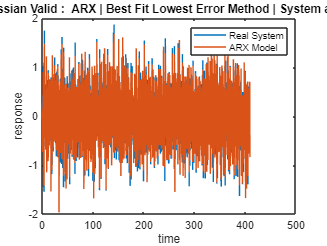

%%
figure()  % figure(1)
plot(t_val,y2_val,t_val,BestFit_y_hat_2)
legend('Real System','ARX Model')
title(" PRBS Ident - Guassian Valid :  ARX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

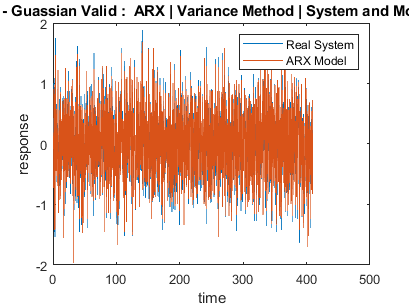


figure()  % figure(2)
plot(t_val,y2_val,t_val,Var_y_hat_2)
legend('Real System','ARX Model')
title(" PRBS Ident - Guassian Valid :  ARX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

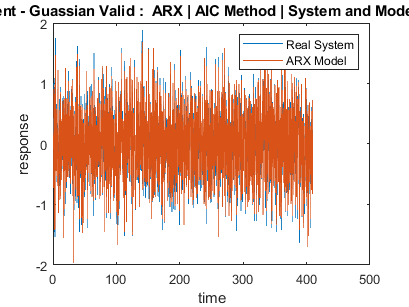


figure()  % figure(3)
plot(t_val,y2_val,t_val,AIC_y_hat_2)
legend('Real System','ARX Model')
title(" PRBS Ident - Guassian Valid :  ARX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

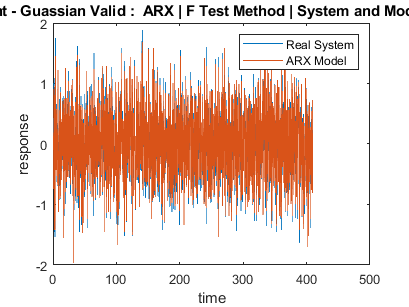


figure()  % figure(4)
plot(t_val,y2_val,t_val,FTest_y_hat_2)
legend('Real System','ARX Model')
title(" PRBS Ident - Guassian Valid :  ARX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")

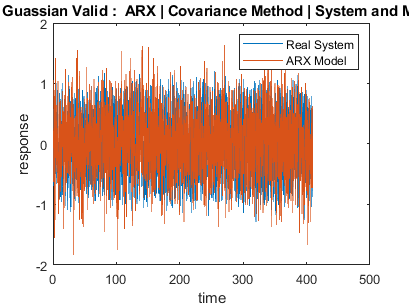


figure()  % figure(7)
plot(t_val,y1_val,t_val,Cov_y_hat_2)
legend('Real System','ARX Model')
title(" PRBS Ident - Guassian Valid :  ARX | Covariance Method | System and Model Response")
xlabel("time")
ylabel("response")

%%

figure()  % figure(5)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Ree_2(2:end), 1:N_val-1, mean(BestFit_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid :  ARX | Best Fit Lowest Errror Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Ree_2(2:end), 1:N_val-1, mean(Var_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid :  ARX | Variance Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Ree_2(2:end), 1:N_val-1, mean(AIC_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid :  ARX | AIC Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Ree_2(2:end), 1:N_val-1, mean(FTest_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid :  ARX | F Test Method | Ree_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")

subplot(5,1,5)
plot(1:N_val-1,Cov_Ree_2(2:end), 1:N_val-1, mean(Cov_Ree_2(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid :  ARX | Covariance Method | Ree_1(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree_1(k)")



%%

figure()  % figure(6)
subplot(5,1,1)
plot(1:N_val-1,BestFit_Rue_2(2:end), 1:N_val-1, mean(BestFit_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid :  ARX | Best Fit Lowest Errror Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(5,1,2)
plot(1:N_val-1,Var_Rue_2(2:end), 1:N_val-1, mean(Var_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid :  ARX | Variance Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(5,1,3)
plot(1:N_val-1,AIC_Rue_2(2:end), 1:N_val-1, mean(AIC_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid :  ARX | AIC Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")

subplot(5,1,4)
plot(1:N_val-1,FTest_Rue_2(2:end), 1:N_val-1, mean(FTest_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid :  ARX | F Test Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")


subplot(5,1,5)
plot(1:N_val-1,Cov_Rue_2(2:end), 1:N_val-1, mean(Cov_Rue_2(2:end))*ones(length(1:N_val-1)))
title(" PRBS Ident - Guassian Valid :  ARX | Covariance Method | Rue_2(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue_2(k)")


fprintf("*****************************************************************\n")
fprintf("*****************************************************************\n")





